# PIDSolver

zeta = 0.5169

OS = 15.0000

phase_margin = 53.1718

w_bw = 96.9143

G_Kp =
 
       9412 s + 9412
  -----------------------
  s^3 + 9 s^2 + 20 s + 12
 
Continuous-time transfer function.



Kp = 94.1236

G_PD =
 
               226.6 s^2 + 9639 s + 9412
  ---------------------------------------------------
  0.003439 s^4 + 1.031 s^3 + 9.069 s^2 + 20.04 s + 12
 
Continuous-time transfer function.


PD =
 
  0.02408 s + 1
  --------------
  0.003439 s + 1
 
Continuous-time transfer function.


G_PI =
 
          1942 s^2 + 1.135e04 s + 9412
  --------------------------------------------
  0.2064 s^4 + 1.857 s^3 + 4.127 s^2 + 2.476 s
 
Continuous-time transfer function.


PI =
 
  0.2064 s + 1
  ------------
    0.2064 s
 
Continuous-time transfer function.

Step response of closed loop G(s):

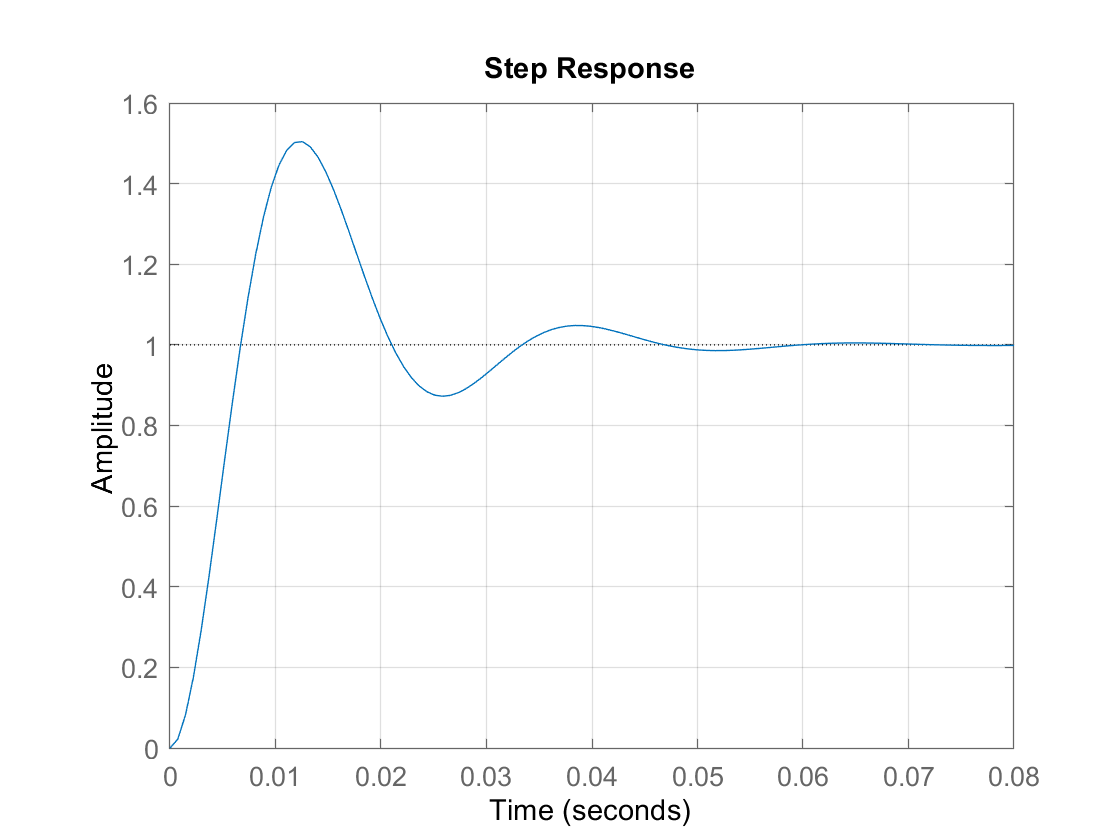

ans = struct with fields:
        RiseTime: 0.0045
    SettlingTime: 0.0440
     SettlingMin: 0.8725
     SettlingMax: 1.5042
       Overshoot: 50.4170
      Undershoot: 0
            Peak: 1.5042
        PeakTime: 0.0125


% testbench:
s = tf('s');
G = (100 * (s+1)) / ((s+1) * (s+2) * (s+6));
Ts = 0.1;
OS = 15;


PIDSolver(G, Ts, OS, 0)

% function description:
% G = Transfer function
% Ts = Settlingtime
% OS = Max % Overshoot
% plotMode = If 0, do not make plots except stepresponse. 
%          = If 1, do all plots

## Sources:

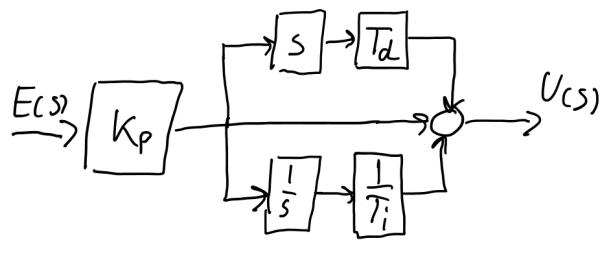

**Source**: E4IRT_L8_vE2101.pdf, page 24.

Note**: **The PID controller is implemented as in the above image. Kp in G_PD(s) and G_PI(s) will be removed respectively (as E(s) already is multiplied by Kp). 

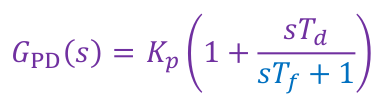

**Source**: E4IRT_L8_vE2101.pdf, page 11.

**Source**: E4IRT_L8_vE2101.pdf, page 18.

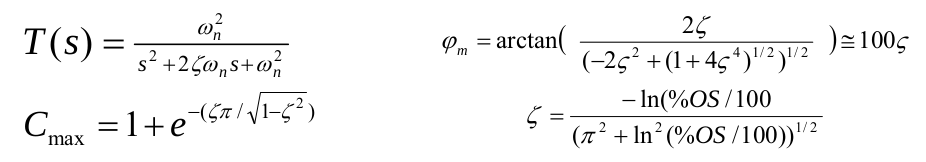

**Source**: Analysis and Design procedure.pdf, page 1.